# Project 1: Linear Regression

## 1. Do “Exercise 2: Linear Regression” from Andrew’s Ng’s OpenClassroom online course: http://openclassroom.stanford.edu/MainFolder/DocumentPage.php?course=MachineLearning&doc=exercises/ex2/ex2.html

% import data
x = load('ex2x.dat');
y = load('ex2y.dat');

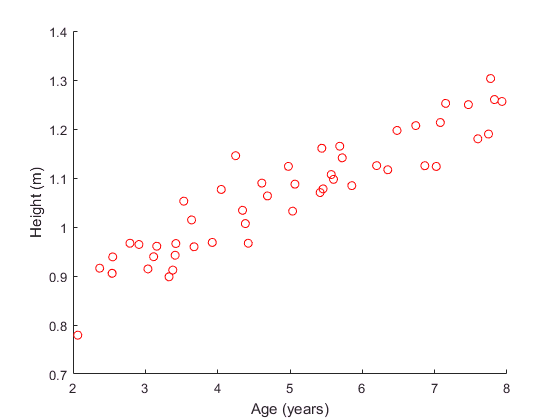

% plot data
hold on
scatter(x,y,'r')
ylabel('Height (m)')
xlabel('Age (years)')
hold off

% Preprocessing
m = length(y);
x = [ones(m,1), x];

## Linear regression

alpha = 0.;
theta = [0,0];
epoch = 1500;

for i = 1:epoch
    theta(i+1,1) = theta(i,1)-(alpha*(1/m)*(sum(((theta(i,:)*x')'-y).*x(:,1))));
    theta(i+1,2) = theta(i,2)-(alpha*(1/m)*(sum(((theta(i,:)*x')'-y).*x(:,2))));
end

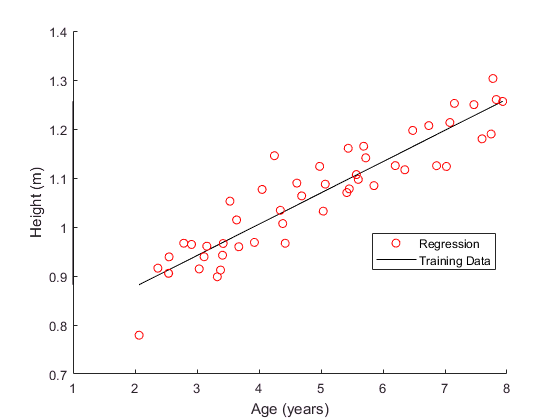

hold on
plot(x,((x(:,2).*theta(end,2))+theta(end,1)),'k')
scatter(x(:,2),y,'r')
xlabel('Age (years)')
ylabel('Height (m)')
legend('Regression','Training Data','location','best')
hold off

age_3 = (3.5*(theta(end,2))+theta(end,1)) 
age_5 = (7*(theta(end,2))+theta(end,1)) 

## Understanding J($\theta$)

J_vals = zeros(100, 100);   % initialize Jvals to 100x100 matrix of 0's
theta0_vals = linspace(-3, 3, 100);
theta1_vals = linspace(-1, 1, 100);
for i = 1:length(theta0_vals)
	  for j = 1:length(theta1_vals)
	      J_vals(i,j) = (1/(2*length(x)))...
           *sum((sum(((x.*[theta0_vals(i),theta1_vals(j)])-y).^2)));
    end
end

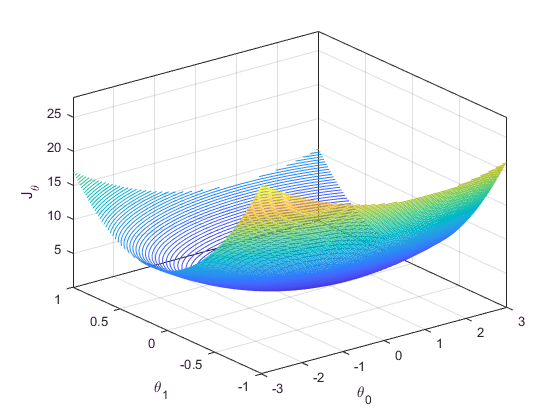

J_vals = J_vals';
figure;
contour3(theta0_vals, theta1_vals, J_vals,100)
xlabel('\theta_0')
ylabel('\theta_1')
zlabel('J_{\theta}')